# 고윳값 및 고유벡터

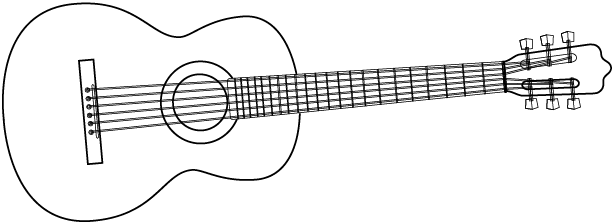

기타의 각 줄은 기본 주파수로 진동하며, 고조파(harmonics)라고 알려진 추가적인 진동 모드가 함께 존재합니다. 이 둘은 함께 풍부하고 상호 보완적인 톤을 만들어냅니다. 시스템의 계산 모델에 대한 고유 분석을 수행하여 이와 같은 자연 진동을 식별할 수 있습니다.

 이 스크립트에서는 고유벡터와 고윳값의 기본 사항을 배웁니다. 

 이 라이브 스크립트는 표시된 코드와 함께 사용하도록 고안되었습니다. `VIEW` 탭을 선택하고 `Output Inline` 로 전환합니다. 

 이 스크립트의 MATLAB 코딩이 어렵다면 MATLAB의 기본 개념을 배울 수 있는 2시간 `분량의` 무료 온라인 튜토리얼 [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) 를 참고하세요  

## 정의

**정의**.  $n \times n$ 정방 행렬 $\mathbf{A}$를 고려해봅시다. 여기서 스칼라 값 $\lambda$에 대해 아래의 식을 만족하는 벡터 $\mathbf{v}$를 고유벡터라고 하며 스칼라 값 $\lambda$를 고윳값이라고 합니다. 


$$\mathbf{A v} = \lambda \mathbf{v}$$


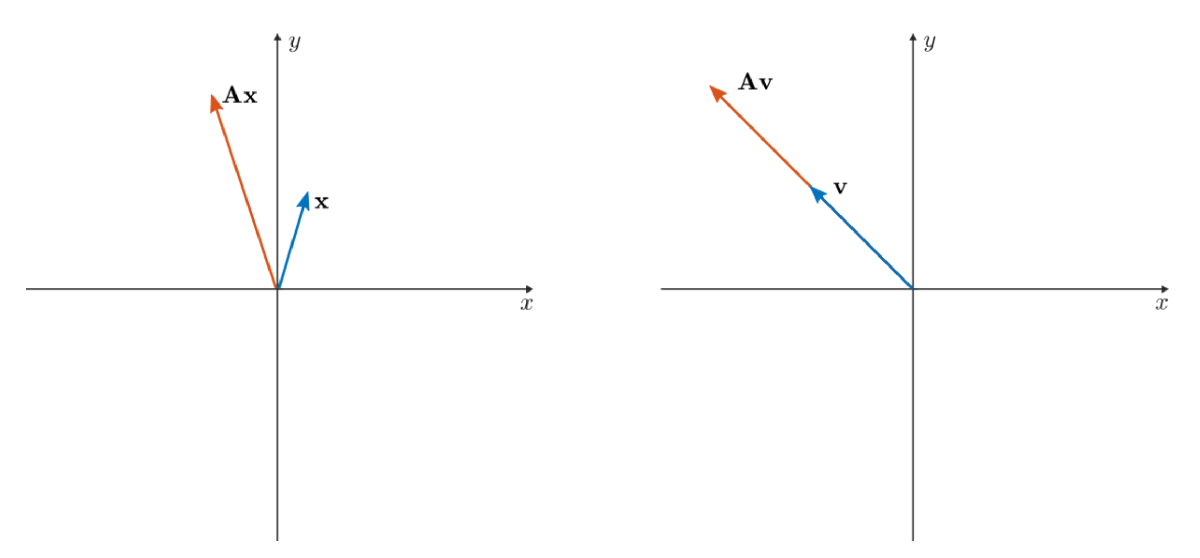

* 대부분의 벡터 *$\mathbf{x}$*는 *$\mathbf{A}$*(왼쪽 그림)와 곱해지면 다른 방향을 가리킵니다. 고유벡터는 예외입니다. 고유벡터는 *$\mathbf{A}$*(오른쪽 그림)를 곱해졌을 때 같은 방향을 가리키는 벡터입니다. *

  ** 실습**

 아래와 같은 2x2 행렬 $\mathbf{A}$를 고려해봅시다. 

A = sym([2 -1; -1 2])

$$A = \left(\begin{array}{cc} 2 & -1\\ -1 & 2 \end{array}\right)$$

-  벡터 $\mathbf{x}$는 아래 $x$ -축과의 각도를 통해 정의됩니다. $\mathbf{x}$가 $\mathbf{A}$의 고유벡터가 되도록 슬라이더를 사용하여 각도 $\theta$를 조정합니다. 

-  $\mathbf{A}$의 고유벡터가 두 개 이상 있습니까? 

-  $\mathbf{A}$ 및 $\mathbf{Ax}$ 값을 바탕으로 찾은 고유벡터에 해당하는 고윳값은 무엇입니까? 

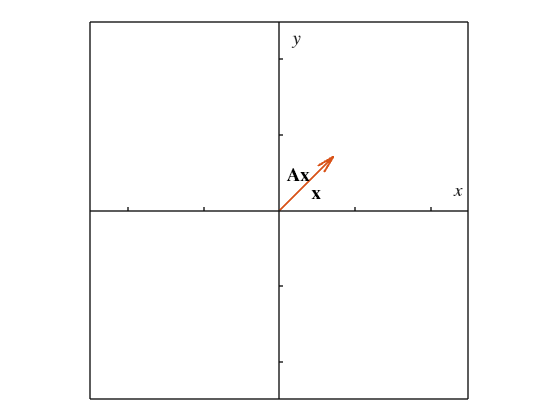

thetad =sym(45);  % 도 단위
x = sym([cosd(thetad); sind(thetad)]);
Ax = sym(A)*x;
% 벡터를 플로팅합니다.
figure
hold on
Setup2DVectorPlot([-2.5 2.5 -2.5 2.5])
PlotVector2D([0 0],double(x),"\mathbf{x}",-0.5)
PlotVector2D([0 0],double(Ax),"\mathbf{Ax}",0.5)
hold off

x

$$x = \left(\begin{array}{c} \frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$

Ax

$$Ax = \left(\begin{array}{c} \frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$

 ** 반영 **

-  정의를 만족하는 고유벡터 $\mathbf{v}$가 있다고 가정합니다. $-\mathbf{v}$도 정의를 충족합니까? 

## 고윳값과 고유벡터 풀기

 다음 두 단계를 사용하여 분석적으로 행렬의 고윳값과 고유벡터를 풀 수 있습니다. 

-  $\lambda$에 대해 $\det(\mathbf{A}-\lambda \mathbf{I}
) = 0$를 풀어 $\mathbf{A}$의 고윳값을 찾습니다. 

-  각 $\lambda$에 대해 선형 시스템 $(\mathbf{A} -  \lambda \mathbf{I} )\mathbf{v} = \mathbf{0}}$을 풀어 $\mathbf{A}$의 고유벡터를 풉니다. 

### 고윳값

 첫 번째 단계(고윳값 해결)를 이해하려면 정의를 고려하십시오. 

고유값 해결? - (solving for the eigenvalues)?

    
$$\mathbf{A v} = \lambda \mathbf{v}$$


 정의를 다음과 같이 다시 작성할 수 있습니다. 

    
$$\begin{array}{rl}
\mathbf{A v} - \lambda \mathbf{v} &= \mathbf{0} 
\\ 
(\mathbf{A } - \lambda \mathbf{I})\mathbf{v} &= \mathbf{0} 
\end{array}$$


-  이 형식에서 고유벡터 $\mathbf{v}$는 행렬 방정식 $(\mathbf{A } - \lambda \mathbf{I})\mathbf{v} = \mathbf{0}$를 풉니다. 

-  행렬 $\mathbf{A}-\lambda \mathbf{I}$가 가역인 경우 이 방정식의 유일한 해는 자명한 해( $\mathbf{v} = \mathbf{0}$)입니다. 

-  따라서 중요한 고유 벡터를 찾으려면 $\mathbf{A}-\lambda \mathbf{I}
$가 **가역적이지 않아야 합니다. **

 정방 행렬은 행렬식 값이 0이 아닌 경우에만 역행렬이 가능하다는 점을 기억하세요. 이는 (자명하지 않은) 고윳값이 

    
$$\det(\mathbf{A}-\lambda \mathbf{I}
) = 0$$


을 충족한다는 것을 의미합니다. 이 방정식의 좌변(LHS)은 *특성 다항식 (characteristic polynomial)*이라고 하는 $\lambda$의 다항식 함수를 생성합니다. 특성 다항식을 풀면 고윳값이 제공됩니다. 

** 예시**. 

    $\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$ 의 고윳값을 구하시오. 

** 정답. ** 고윳값은 $\det(\mathbf{A} - \lambda \mathbf{I}) = 0$ : 

    $\mathbf{A} - \lambda \mathbf{I} = 
\left(\begin{array}{cc} 
2 & -1\\
-1 & 2
\end{array}\right)
-
\left(\begin{array}{cc} 
\lambda & 0\\
0 & \lambda
\end{array}\right)
=
\left(\begin{array}{cc} 
2 - \lambda & -1\\
-1 & 2 - \lambda
\end{array}\right)
$ , 

 을 풀어서 얻을 수 있습니다. $\det( \mathbf{A} - \lambda \mathbf{I} )= \left|\begin{array}{cc}
2 - \lambda & -1\\
-1 & 2 - \lambda
\end{array}\right|
= (2-\lambda)(2-\lambda) - (-1)(-1) = \lambda^2 - 4\lambda +3$

 특성 다항식을 0으로 설정하고 계산 결과: 

    
$$\lambda^2 - 4\lambda + 3 = 0 \\ \lambda = 1,  3$$


** 연습 **. MATLAB에서 

    
$$\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$$


의 고윳값을 구합니다. 

  ** 프로팁**. [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html) 함수를 사용하여 MATLAB에서 숫자형 행렬 `A`의 고윳값을 풀 수 있습니다. 기본 구문은 

 입니다. 이 함수의 결과는 두 개의 행렬입니다: A의 고유벡터를 열로 가지는 행렬 V와 고유값을 포함하는 대각 행렬 D.

** 연습 **. 행렬 

     $\mathbf{B} = \left(\begin{array}{cc}
1 &  2\\
-3 & -6
\end{array}\right)$ 을 고려하십시오. 

 (a) 손으로 직접 계산하여 $\mathbf{B}$의 고윳값을 찾아보세요 

 (b) MATLAB을 이용하여 고윳값을 계산하고 결과를 확인해보세요. 

### **고유벡터**

 고윳값을 식별한 후 각 $\lambda$에 대해 선형 시스템 

    
$$(\mathbf{A} -  \lambda \mathbf{I} )\mathbf{v} = \mathbf{0}}$$


을 풀어 고유벡터를 풀 수 있습니다. 

** 예 **. $\lambda = 1$ 에 해당하는 

    
$$\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$$


의 고유벡터를 구합니다. 

** 정답 **. 

    
$$(\mathbf{A} -  1 \mathbf{I})\mathbf{v} = 0 
\quad
\rightarrow 
\quad
\left[
\left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)
-
\left(\begin{array}{cc}
1 &  0\\
0 & 1
\end{array}\right)
\right]
\left(\begin{array}{cc}
v_1 \\
v_2 
\end{array}\right)
=
\left(\begin{array}{cc}
0 \\
0
\end{array}\right)

\quad
\rightarrow 
\quad
\left(\begin{array}{cc}
1 & -1\\
-1 & 1
\end{array}\right)
\left(\begin{array}{cc}
v_1 \\
v_2 
\end{array}\right)
=
\left(\begin{array}{cc}
0 \\
0
\end{array}\right)
$$


 첨가 행렬(augmented matrix)과 행 소거를 수행합니다. 

    
$$\left(\begin{array}{cc}
1 & -1\\
-1 & 1
\end{array}\right.
\ \left| \ \begin{array}{cc}
0 \\
0
\end{array}\right)
\quad \rightarrow \quad
\left(\begin{array}{cc}
1 & -1\\
0 & 0
\end{array}\right.
\ \left| \ \begin{array}{cc}
0 \\
0
\end{array}\right)$$


 이는 해가 다음을 충족한다는 것을 의미합니다. 

    
$$v_1 - v_2 = 0$$


 $v_1$의 선택은 임의적입니다. $v_1 = 1$ 로 설정하면 $v_2 = v_1 = 1$ 를 의미하며 고유벡터 

    $\mathbf{v} = \left( \matrix{ 1 \cr 1 }\right)$ 을 생성합니다. 

** 연습 **. $\lambda = 3$ 에 해당하는 

    
$$\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$$


의 고유벡터를 구합니다. 

showSoln = false;
A = sym([2 -1; -1 2]);  
if(showSoln)
    [V,D] = eig(A);
    v = V(:,2)
end

  ** 실습. ** MATLAB에서 $\mathbf{Av}$ 및 $\lambda \mathbf{v}$를 계산하여 $\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$에 대한 고유벡터/고윳값 쌍 

    $\lambda = 1$ 및 $\mathbf{v} = \left( \matrix{ 1 \cr 1 }\right)$가 정의를 충족하는지 확인합니다. `v` 및 `A` 를 정의하는 것부터 시작하세요. 

 ** 반영 **

-  정의에는 $\mathbf{A v} = \lambda \mathbf{v}$ 가 필요합니다. 특정 $\lambda$에 해당하는 $\mathbf{v}$이 하나만 있습니까? 

-  행렬 $\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$ 의 경우 $\mathbf{v} = \left( \matrix{ 1 \cr 1 }\right)$ 은 $\lambda = 1$ 에 해당하는 고유벡터입니다. $\lambda = 1$에 해당하는 다른 고유벡터를 찾을 수 있나요? 

-  $\lambda = 1%$의 경우, 가능한 모든 고유벡터에 대해 무엇이 참일까요? 

** 연습문제 **. 행렬 

    
$$\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$$


를 고려하십시오. $\mathbf{A}$의 숫자(numeric) 및 기호(symbolic) 버전이 아래에 정의되어 있습니다. 

A = [2 -1; -1 2]; % numeric A
Asym = sym(A); % symbolic A

 (a) MATLAB을 사용하여 `A` `(numeric version`)의 고유벡터를 구해보세요. 

 (b) MATLAB을 사용하여 `Asym`(symbolic version)의 고유벡터를 구해보세요. 

** 힌트**: [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html). 

 ** 반영 **

-  Symbolic Math Toolbox로 계산된 고유벡터는 숫자 행렬을 사용하여 계산된 고유벡터와 다릅니다. 두 쌍의 고유벡터가 모두 유효합니까? 

-  $\mathbf{A v} = \lambda \mathbf{v}$ 정의를 사용하여 $\mathbf{v}$의 스칼라 배수가 해당 고윳값에 대한 유효한 고유벡터임을 보여줍니다. 

-  일반적으로 고유벡터에는 두 가지 공통 형식이 선택됩니다. 그들은 무엇입니까? 그들이 선택된 이유는 무엇입니까? 

## 고유 분해

** 정의 **. $n$ 개의 선형 독립 고유 벡터가 있는 $n \times n$ 행렬 $\mathbf{A}$는 

    $\mathbf{A} = \mathbf{V \Lambda V}^{-1}$, 

로 분해될 수 있습니다. 여기서 $\mathbf{V}$는 열이 $\mathbf{A}$의 고유 벡터인 행렬이고 $\mathbf{\Lambda}$은 해당 고윳값을 포함하는 대각 행렬입니다. 

    $\mathbf{V} =
\left(\begin{array}{c}
\\
v_1
\\
\\
\\
\end{array} \right| 
\left. \begin{array}{c}
\\
v_2
\\
\\
\\
\end{array}\right|
\left. \begin{array}{c}
\\
\cdots
\\ \\ \\
\end{array}\right|
\left. \begin{array}{c}
\\
v_n
\\
\\
\\
\end{array}\right)$ 그리고 $\mathbf\Lambda =
\left( \matrix{
\lambda_1 & & & \mathbf{0}
\cr
 & \lambda_2 & & 
\cr
 & & \ddots & 
\cr
\mathbf{0} & & & \lambda_n
}
\right)$. 

 이 인수분해는* 행렬 대각화 * 라고도 합니다. 

** 예시**. 

    $\mathbf{A} = \left(\begin{array}{cc}
2 & -1\\
-1 & 2
\end{array}\right)$ 을 고려하십시오. 

 (a) $\mathbf{A}$는 대각화 가능합니까? (b) 그렇다면 행렬 대각화를 풀어보세요. 

** 정답 **. 

 (a) 고윳값과 쌍을 이루는 고유벡터 집합은 

    $\lambda_1 = 1, \ \mathbf{v}_1 = \left( \matrix{ 1 \cr 1} \right)$ 및 $\lambda_2 = 3, \ \mathbf{v}_2 = \left( \matrix{ 1 \cr -1} \right)$

입니다. $\mathbf{v}_1$와 $\mathbf{v}_2$는 선형 독립이므로 $\mathbf{A}$은 대각화 가능합니다. 

 (b) 고윳값/고유벡터 쌍 사용: 

    
$$\mathbf{A} = \mathbf{V \Lambda V}^{-1}$$


        
$$=
\left(\begin{array}{c}
\\
v_1
\\ \\ \\
\end{array} \right| 
\left. \begin{array}{c}
\\
v_2
\\ \\ \\
\end{array}\right)
\left(\begin{array}{c}
\lambda_1 & 0 
\\
0 & \lambda_2
\end{array}\right)
\left(\begin{array}{c}
\\
v_1
\\ \\ \\
\end{array} \right| 
\left. \begin{array}{c}
\\
v_2
\\ \\ \\
\end{array}\right)^{-1}
$$


        
$$=
\left(\begin{array}{c}
1 &1 \\
1 & -1
\end{array}\right)
\left(\begin{array}{c}
1 & 0 
\\
0 & 3
\end{array}\right)
\left(\begin{array}{c}
1 &1 \\
1 & -1
\end{array}\right)^{-1}
$$


        
$$=
\left(\begin{array}{c}
1 &1 \\
1 & -1
\end{array}\right)
\left(\begin{array}{c}
1 & 0 
\\
0 & 3
\end{array}\right)
\left(\begin{array}{c}
1/2 & 1/2 \\
1/2 & -1/2
\end{array}\right)
$$


 ** 반영 **

-  MATLAB에서 이전 예제의 행렬을 곱하여 행렬 곱 $\mathbf{V \Lambda V}^{-1}$이 $\mathbf{A}$와 같은지 확인합니다. $\mathbf{V}$ 및 $\mathbf{\Lambda}}$ 를 정의하는 것부터 시작하세요. 

% 여기에 코드를 작성하세요




-  [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html) 및 [`inv`](https://www.mathworks.com/help/matlab/ref/inv.html) 함수를 사용하여 $\mathbf{A}$의 고유 분해를 해결합니다. 

A = [2 -1; -1 2]; % A의 정의
% 여기에 코드를 작성하세요




-  대각화가 고유합니까? 

** 연습 **. 행렬 

    $\mathbf{C} = \left(\begin{array}{cc}
3 & 5\\
0 & -2
\end{array}\right)$ 에 대하여, 

 (a) 고윳값과 고유벡터를 직접 풀어보세요. 

 (b) 고윳값과 고유벡터로부터 $\mathbf{C}$의 고유 분해를 형성합니다. 

 (c) 아래 $\mathbf{C}$을 정의한 다음 [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html) 및 [`inv`](https://www.mathworks.com/help/matlab/ref/inv.html) 함수를 사용하여 MATLAB에서 고유 분해를 계산하여 답을 확인합니다. 

% C의 고유 분해를 해결합니다.




## 비가역 행렬의 고윳값

 행렬에 고윳값 $\lambda = 0$이 있다고 가정합니다. 해당 고윳값의 경우: 

    $\det(\mathbf{A}-0\mathbf{I}
) = \det(\mathbf{A}) = 0$. 

 이는 고윳값이 0인 경우 $\mathbf{A}$ 행렬의 역행렬이 존재할 수 없음을 의미합니다. 따라서 $\mathbf{A}$가 가역이 되려면 $\mathbf{A}$의 모든 고윳값이 0이 아니어야 합니다. 

** 정리 **. $n \times n$ 행렬은 0이 아닌 고윳값을 $n$개 갖는 경우에만 역행렬이 존재할 수 있습니다. 

** 연습 **. 행렬 $\mathbf{G}$ 및 $\mathbf{H}$가 다음과 같을 때, 

G = [1 2 3; 4 5 6; 7 8 9]

G =      1     2     3
     4     5     6
     7     8     9


H = [1 2 3; 4 5 0; 7 8 0]

H =      1     2     3
     4     5     0
     7     8     0


위에 정의된 각 행렬에 대해 고윳값과 행렬식을 계산하는 두 가지 방법으로 역행렬이 가능한지 확인하십시오. 

** 힌트 ** : [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html) 및 [`det`](https://www.mathworks.com/help/matlab/ref/det.html). [`sym`](https://www.mathworks.com/help/symbolic/sym.html) 명령을 `sym(G)` 와 같이 사용하여 행렬을 기호 행렬로 변환해 볼 수도 있습니다. 

 (a) $\mathbf{G}%$ 에 대한 분석을 수행합니다.

 (b) $\mathbf{H}$ 에 대한 분석을 수행합니다.

 **반영. **

-  $10^{-16}$ 수준의 행렬식 또는 고윳값은 무엇을 암시합니까? 

-  이러한 맥락에서 [`eps`](https://www.mathworks.com/help/matlab/ref/eps.html)의 의미는 무엇입니까? 이 섹션을 실행하여 `eps` 값을 확인하세요. 

eps

ans = 2.2204e-16

## 결함 행렬 (defective matrices)

** 정의 **. $n$ 선형 독립 고유 벡터를 갖지 않는 $n \times n$ 행렬을 *결함 행렬*이라고 합니다. 

-  결함이 있는 행렬은 대각화할 수 없습니다. 

-  일부 역행렬(예: 아래 표시된 * 조던 행렬 * )은 결함 행렬입니다.

** 예 **. 아래에 정의된 $3 \times 3$ 조던 행렬 $\mathbf{J}$가 다음과 같을 때, 

J = sym(diag([4 4 4]) + diag([1 1],1))

$$J = \left(\begin{array}{ccc} 4 & 1 & 0\\ 0 & 4 & 1\\ 0 & 0 & 4 \end{array}\right)$$

 [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html)`를` 사용하여 $\mathbf{J}$의 고유벡터를 계산합니다.

[V,D] = eig(J) 

$$V = \left(\begin{array}{c} 1\\ 0\\ 0 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} 4 & 0 & 0\\ 0 & 4 & 0\\ 0 & 0 & 4 \end{array}\right)$$

`eig`의 고유벡터 출력에는 단 하나의 고유벡터가 있습니다. 이는 행렬에 결함이 있고 독립 고유 벡터가 하나만 있기 때문에 발생했습니다. 그러나 이 행렬은 가역적입니다. 아래에서 계산된 $\mathbf{J}$의 행렬식을 고려해보세요. 

detJ = det(J)

$$detJ = 64$$

 $\mathbf{J}$의 행렬식은 고윳값의 곱과 같습니다. 이는 일반적인 사실입니다. 

-  행렬의 행렬식은 고윳값의 곱과 같습니다. 

** 연습 **. 아래에 정의된 행렬이 아래와 같을 때 

D = sym(diag([2 2 3]))

$$D = \left(\begin{array}{ccc} 2 & 0 & 0\\ 0 & 2 & 0\\ 0 & 0 & 3 \end{array}\right)$$

K = sym(diag([2 2 3]) + diag([1 1],1))

$$K = \left(\begin{array}{ccc} 2 & 1 & 0\\ 0 & 2 & 1\\ 0 & 0 & 3 \end{array}\right)$$

 각 행렬에 대해 다음 질문에 대해 생각해봅시다.  

-  행렬에 결함이 있습니까? 

-  행렬의 역행렬이 존재합니까?

** 힌트 **. MATLAB을 사용하여 행렬 특성에 대한 정보를 제공하는 계산을 수행합니다. 

 (a) $\mathbf{D}$ 에 대해 확인해보세요

 (b) $\mathbf{K}$ 에 대해 확인해보세요 

 ** 생각해봅시다.**

-  모든 비가역 행렬에 결함이 있습니까? 

-  결함이 있는 행렬은 모두 비가역적입니까? 

-  행렬의 가역성과 결함 사이에 명백한 관계가 있습니까? 

## 응용 프로그램: 진동 질량 및 위험 평가

 응용 프로그램을 보려면 라이브 스크립트 [eigenAnalyticApplications_ko.mlx](matlab: open eigenAnalysisApplications_ko.mlx)를 엽니다. 이 링크가 작동하려면 라이브 스크립트가 [MATLAB 검색 경로](https://www.mathworks.com/help/matlab/matlab_env/what-is-the-matlab-search-path.html)에 있어야 합니다. 

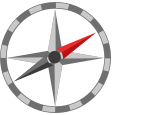** 추가 탐색 **

- 온라인 교육 과정[ Introduction to Linear Algebra with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-linear-algebra-with-matlab/linalg)에서 행렬 연산 및 기타 선형 대수 주제에 대해 자세히 알아볼 수 있습니다. 

- Symbolic Math에 대해 자세히 알아보려면 온라인 교육 과정 [Introduction to Symbolic Math with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-symbolic-math-with-matlab/symbolic)을 확인하세요. 

 시각화 함수

function Setup2DVectorPlot(AxisLims) 
% 2D 벡터 시각화를 위한 멋진 축 설정
    fs = 14; % 그래프의 글꼴 크기
    ax = gca;
    ax.XAxisLocation = "origin";
    ax.YAxisLocation = "origin";    
    ax.Position = [0.05 0.05 0.9 0.9];
    axis equal tight
    axis(AxisLims)
    box on
    xlabel("$x$","Interpreter","latex","fontsize",fs)
    ylabel("$y$","Interpreter","latex","fontsize",fs)
    ax.XTick = round(AxisLims(1)):round(AxisLims(2));
    ax.XTickLabel = [];
    ax.YTick = round(AxisLims(1)):round(AxisLims(2));
    ax.YTickLabel = [];
end

% 주어진 이름으로 2D 벡터를 시각화합니다.
function PlotVector2D(u0,u,name,NameOffset) 
    fs = 14; % 그래프의 글꼴 크기
    quiver(u0(1),u0(2),u(1),u(2),"autoscale","off","maxheadsize",1/sqrt(dot(u,u)),"linewidth",1.5)
    offset = null(u')/3*NameOffset;
    text(u0(1) + u(1)/2 + offset(1), u0(2) + u(2)/2 + offset(2),strcat("$",name,"$"), ...
        "Interpreter","latex","fontsize",fs,"HorizontalAlignment","center")
end


Suppress unused suggestions

%#ok<*IJCL> 
%#ok<*NOPRT>
%#ok<*UNRCH>
%#ok<*ASGLU> 
%#ok<*NASGU>